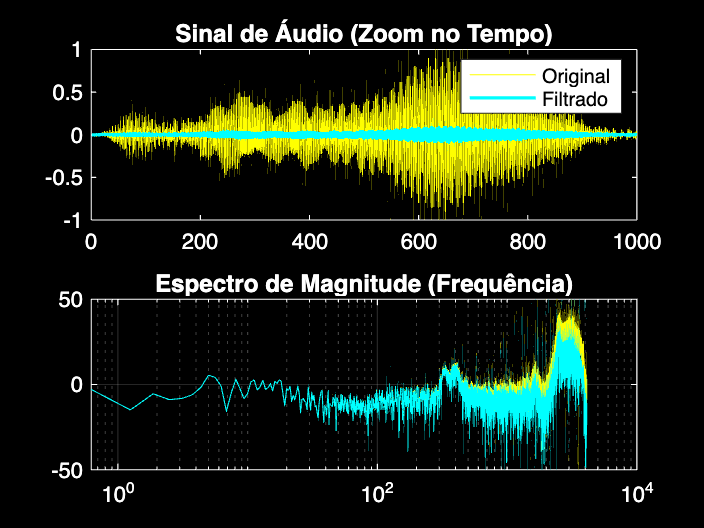

%% Encerramento - Filtragem de Áudio via FFT
clear; clc;

% 1. Carregamento do Sinal
load chirp;
x   = y;
fs  = Fs;
x = x(:,1); % Mono
L = length(x);

% 2. Transformada de Fourier do Áudio (FFT)
X_freq = fft(x);

% 3. Definição do Filtro RC na Frequência
% Criamos um vetor de frequências que corresponde à FFT
f = (0:L-1)*(fs/L); 
w = 2*pi*f;

% Função de Transferência do Filtro RC: H(jw) = 1 / (1 + jwRC)
fc = 800; 
RC = 1/(2*pi*fc);
H_w = 1 ./ (1 + 1j*w*RC);

% 4. Filtragem: Multiplicação Ponto a Ponto (Domínio da Frequência)
Y_freq = X_freq .* H_w'; 

% 5. Retorno ao Tempo (FFT Inversa)
y = real(ifft(Y_freq));

% --- VISUALIZAÇÃO ---
figure('Color', 'k', 'Name', 'Processamento via FFT');
subplot(2,1,1);
plot(x(1:1000), 'y'); hold on; plot(y(1:1000), 'c', 'LineWidth', 1.5);
title('Sinal de Áudio (Zoom no Tempo)', 'Color', 'w');
legend('Original', 'Filtrado');
set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w');

subplot(2,1,2);
% Plotando apenas metade do espectro (simetria)
f_plot = f(1:floor(L/2));
X_mag = abs(X_freq(1:floor(L/2)));
Y_mag = abs(Y_freq(1:floor(L/2)));

semilogx(f_plot, 20*log10(X_mag), 'y'); hold on;
semilogx(f_plot, 20*log10(Y_mag), 'c');
title('Espectro de Magnitude (Frequência)', 'Color', 'w');
grid on; set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w');


% 6. Ouvir o resultado
sound(y(1:end), fs); 